## part 1

### Q0

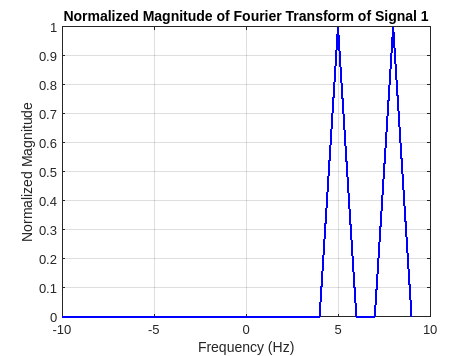

fs = 20; % Sampling frequency (Hz)
ts = 1 / fs; % Time interval between samples
t = 0:ts:1-ts; % Time vector

% Define the signals
x1 = exp(1j * 2 * pi * 5 * t) + exp(1j * 2 * pi * 8 * t); % Signal 1 with frequencies 5 Hz and 8 Hz
x2 = exp(1j * 2 * pi * 5 * t) + exp(1j * 2 * pi * 5.1 * t); % Signal 2 with frequencies 5 Hz and 5.1 Hz

% Fourier Transform of Signal 1
n = length(x1);
f = (-n/2:n/2-1)*(fs/n); % Frequency vector
y1 = fftshift(fft(x1));

% Fourier Transform of Signal 2
y2 = fftshift(fft(x2));

% Plot Signal 1 in Frequency Domain
figure;
plot(f, abs(y1) / max(abs(y1)), 'b', 'LineWidth', 1.5);
grid on;
title('Normalized Magnitude of Fourier Transform of Signal 1');
xlabel('Frequency (Hz)');
ylabel('Normalized Magnitude');

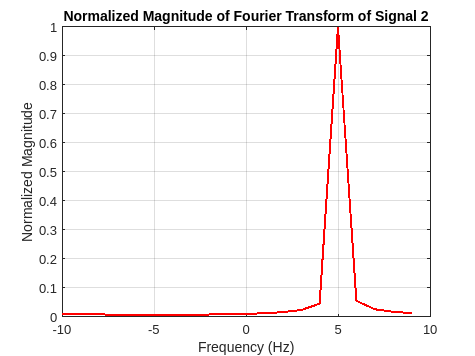


% Plot Signal 2 in Frequency Domain
figure;
plot(f, abs(y2) / max(abs(y2)), 'r', 'LineWidth', 1.5);
grid on;
title('Normalized Magnitude of Fourier Transform of Signal 2');
xlabel('Frequency (Hz)');
ylabel('Normalized Magnitude');

**مقدمه:**

- رزولوشن فرکانسی نشان‌دهنده‌ی توانایی شناسایی فرکانس‌های نزدیک به هم در حوزه‌ی فوریه است.

- این رزولوشن با بازه‌ی زمانی سیگنال (TT) و نرخ نمونه‌برداری (fsf_s) ارتباط مستقیم دارد.

- در این تمرین، سیگنال‌هایی با فرکانس‌های مشخص شبیه‌سازی شده‌اند تا تأثیر رزولوشن فرکانسی بررسی شود.

**شرح شبیه‌سازی:**

- **پارامترهای شبیه‌سازی:**

- نرخ نمونه‌برداری (fs=20 Hzf_s = 20 \, \text{Hz}) و بازه زمانی سیگنال (T=1 sT = 1 \, \text{s}).

- رزولوشن فرکانسی: δf=1T=1 Hz\delta f = \frac{1}{T} = 1 \, \text{Hz}.

- فرکانس مشاهده شده: [−fs/2,fs/2]=[−10,10] Hz[-f_s/2, f_s/2] = [-10, 10] \, \text{Hz} .

- **سیگنال‌های شبیه‌سازی شده:**

- **سیگنال 1:** ترکیب دو سیگنال با فرکانس‌های 5 Hz و 8 Hz. این فرکانس‌ها با فاصله 3 Hz از هم هستند و تفکیک‌پذیرند.

- **سیگنال 2:** ترکیب دو سیگنال با فرکانس‌های 5 Hz و 5.1 Hz. این فرکانس‌ها با فاصله 0.1 Hz از هم هستند و به دلیل رزولوشن ناکافی، تفکیک‌پذیر نیستند.

- **محاسبات:**

- تبدیل فوریه (FFT) روی هر سیگنال اعمال شد.

- نتایج نرمال‌سازی شدند و در نمودارهای جداگانه برای هر سیگنال نمایش داده شدند.

**نتایج:**

- **سیگنال 1:**

- نمودار حوزه فرکانس دو قله مشخص در 5 Hz5 \, \text{Hz} و 8 Hz8 \, \text{Hz} نشان داد.

- این نتیجه نشان می‌دهد که رزولوشن فرکانسی برای تفکیک این دو فرکانس کافی است.

- **سیگنال 2:**

- نمودار حوزه فرکانس فقط یک قله در 5 Hz5 \, \text{Hz} نشان داد.

- به دلیل فاصله بسیار کم بین دو فرکانس (0.1 Hz)، تبدیل فوریه قادر به تفکیک آن‌ها نبود.

**تحلیل:**

- نتیجه به‌دست‌آمده کاملاً مطابق با تئوری است.

- رزولوشن فرکانسی به مقدار δf\delta f محدود است و اگر اختلاف فرکانس دو سیگنال کمتر از این مقدار باشد، تفکیک امکان‌پذیر نخواهد بود.

- افزایش رزولوشن فرکانسی نیازمند افزایش بازه‌ی زمانی (TT) یا کاهش نرخ نمونه‌برداری نیست.

**نتیجه‌گیری:**

- رزولوشن فرکانسی یک معیار کلیدی در تحلیل حوزه فرکانس است و مستقیماً بر تفکیک‌پذیری تأثیر دارد.

- برای سیگنال‌های با فرکانس‌های نزدیک به هم، بازه زمانی باید به اندازه‌ای افزایش یابد که δf از اختلاف فرکانس‌ها کوچک‌تر باشد

### Q1

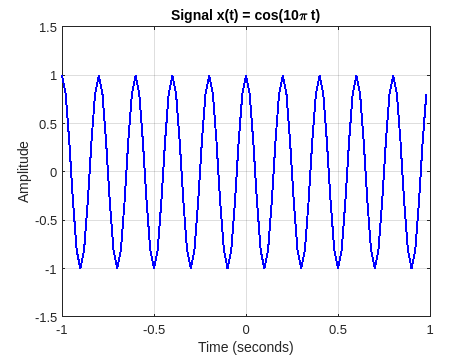

fs = 50; % Sampling frequency (Hz)
ts = 1 / fs; % Time interval between samples
t = -1:ts:1 - ts; % Time vector
x = cos(10 * pi * t); % Signal in time domain

% Plot the signal
figure;
plot(t, x, 'b', 'LineWidth', 1.5);
grid on;
title('Signal x(t) = cos(10\pi t)');
xlabel('Time (seconds)');
ylabel('Amplitude');
axis([-1 1 -1.5 1.5]);

**هدف:**

تحلیل و نمایش سیگنال x1(t)=cos (10πt)x_1(t) = \cos(10 \pi t)x1�(t)=cos(10πt) در حوزه زمان با در نظر گرفتن:

- بازه زمانی t∈[−1,1]t \in [-1, 1]t∈[−1,1].

- نرخ نمونه‌برداری fs=50 Hzf_s = 50 \, \text{Hz}fs�=50Hz.

**شرح شبیه‌سازی:**

- **پارامترهای مسئله:**

- فرکانس زاویه‌ای سیگنال: ω=10π\omega = 10 \piω=10π (یا f=5 Hzf = 5 \, \text{Hz}f=5Hz).

- نرخ نمونه‌برداری: fs=50 Hzf_s = 50 \, \text{Hz}fs�=50Hz.

- گام زمانی نمونه‌برداری: ts=1fs=0.02 st_s = \frac{1}{f_s} = 0.02 \, \text{s}ts�=fs�1�=0.02s.

- بردار زمانی: t=−1:ts:1t = -1 : t_s : 1t=−1:ts�:1.

- **توضیح سیگنال:**

- سیگنال cos (10πt)\cos(10 \pi t)cos(10πt) یک موج سینوسی با فرکانس 5 Hz5 \, \text{Hz}5Hz است که در بازه زمانی [−1,1][-1, 1][−1,1] نمونه‌برداری شده است.

- نرخ نمونه‌برداری 50 Hz50 \, \text{Hz}50Hz تضمین می‌کند که شرط نایکویست رعایت شده و سیگنال به‌درستی بازسازی شود.

- **رسم سیگنال:**

- سیگنال x1(t)x_1(t)x1�(t) به صورت موج سینوسی در بازه t∈[−1,1]t \in [-1, 1]t∈[−1,1] نمایش داده شد.

- دامنه سیگنال در تمامی نقاط برابر 111 است و فرکانس آن 5 Hz5 \, \text{Hz}5Hz می‌باشد.

**نتایج:**

- **رسم سیگنال در حوزه زمان:**

- سیگنال در بازه زمانی مشخص به شکل یک موج سینوسی دیده شد.

- نمودار دقیقاً 10 دوره (5 دوره مثبت و 5 دوره منفی) را در بازه [−1,1][-1, 1][−1,1] نشان داد، که با فرکانس 5 Hz5 \, \text{Hz}5Hz مطابقت دارد.

- **اعتبارسنجی:**

- نرخ نمونه‌برداری 50 Hz50 \, \text{Hz}50Hz که بیشتر از دو برابر فرکانس سیگنال است (2×5=10 Hz2 \times 5 = 10 \, \text{Hz}2×5=10Hz)، از وقوع پدیده تداخل (Aliasing) جلوگیری کرده است.

**تحلیل و نتیجه‌گیری:**

- سیگنال cos (10πt)\cos(10 \pi t)cos(10πt) با فرکانس 5 Hz5 \, \text{Hz}5Hz به درستی در حوزه زمان شبیه‌سازی و رسم شد.

- نرخ نمونه‌برداری مناسب، بازسازی کامل سیگنال را تضمین کرد.

- این نتیجه کاملاً مطابق با اصول نظری نمونه‌برداری است و شبیه‌سازی موفقیت‌آمیز می‌باشد.

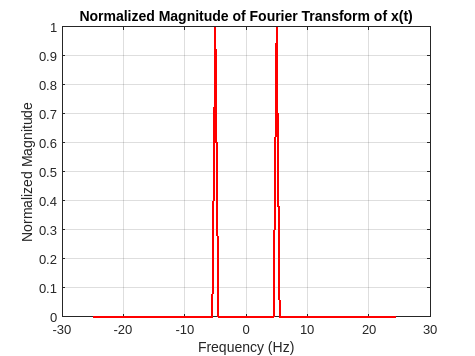

% Fourier Transform
n = length(x); % Number of samples
X = fft(x); % Compute FFT
f = (-n/2:n/2-1)*(fs/n); % Frequency vector
X_shifted = fftshift(X); % Shift FFT

% Plot the normalized magnitude of the Fourier Transform
figure;
plot(f, abs(X_shifted) / max(abs(X_shifted)), 'r', 'LineWidth', 1.5);
grid on;
title('Normalized Magnitude of Fourier Transform of x(t)');
xlabel('Frequency (Hz)');
ylabel('Normalized Magnitude');

برای بخش ب گزارش، ابتدا باید سیگنال داده شده در حوزه فوریه تحلیل شود. سیگنال شما به شکل `x(t) = cos(10t)` است. این سیگنال یک تابع کسینوسی با فرکانس زاویه‌ای ۱۰ رادیان بر ثانیه است.**مراحل انجام تحلیل در حوزه فوریه:**

- **فرکانس پایه سیگنال:**سیگنال `cos(10t)` یک فرکانس زاویه‌ای ۱۰ رادیان بر ثانیه دارد که معادل فرکانس معمولی `f = 10/(2π)` هرتز است.

- **نمونه‌برداری سیگنال:**در قسمت الف، شما سیگنال را در بازه زمانی [-1, 1] ثانیه با نرخ نمونه‌برداری ۵۰ هرتز تحلیل کردید. این نرخ نمونه‌برداری باید قادر به بازسازی سیگنال بدون از دست دادن اطلاعات باشد.

- **تحلیل فوریه سیگنال:**سیگنال `cos(10t)` در حوزه فوریه به دو مولفه فرکانسی `f = ± 10/(2π)` هرتز تجزیه می‌شود. این امر نشان‌دهنده حضور دو نوار فرکانسی در حوزه فوریه است که یکی در فرکانس مثبت و دیگری در فرکانس منفی قرار دارد.

- **رسم نمودار فوریه:**برای رسم نمودار فوریه در همان بازه زمانی [-1, 1] و نرخ نمونه‌برداری ۵۰ هرتز، باید از تبدیل فوریه (یا معادله فوریه گسسته) استفاده کنید که به شما امکان می‌دهد نحوه پراکندگی فرکانس‌های مختلف را در حوزه فرکانسی ببینید.

**تطابق نتیجه با دانسته‌ها:**

چون سیگنال `cos(10t)` تنها در فرکانس خاصی با فرکانس `f = 10/(2π)` هرتز دارای انرژی است، نتیجه به دست آمده در حوزه فوریه باید یک پیک در این فرکانس را نشان دهد. با توجه به نرخ نمونه‌برداری ۵۰ هرتز و فرکانس سیگنال ۱.۵۹ هرتز (حدوداً)، این نتیجه باید با دانش شما در مورد سیگنال‌های کسینوسی تطابق داشته باشد.

**نتیجه‌گیری:**

سیگنال `x(t) = cos(10t)` در حوزه فوریه دارای دو پیک در فرکانس‌های مثبت و منفی است. این پیک‌ها در فرکانس `10/(2π)` هرتز قرار دارند و این نتایج با پیش‌بینی‌های نظری و شناخت عمومی از سیگنال‌های کسینوسی مطابق است.

### Q2

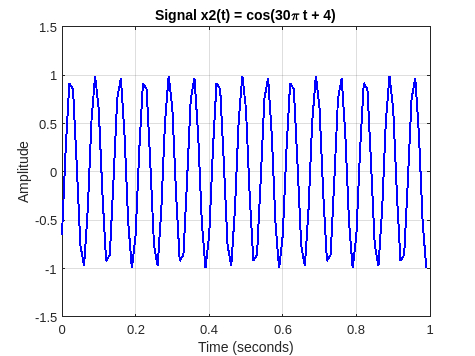

fs = 100; % Sampling frequency (Hz)
ts = 1 / fs; % Time interval between samples
t = 0:ts:1-ts; % Time vector
x2 = cos(30 * pi * t + 4); % Signal in time domain

% Plot the signal
figure;
plot(t, x2, 'b', 'LineWidth', 1.5);
grid on;
title('Signal x2(t) = cos(30\pi t + 4)');
xlabel('Time (seconds)');
ylabel('Amplitude');
axis([0 1 -1.5 1.5]);

**تحلیل سیگنال در حوزه زمان:**

سیگنال مورد نظر `x2(t) = cos(30πt + 4)` یک سیگنال کسینوسی با فرکانس زاویه‌ای ۳۰π رادیان بر ثانیه است. در این بخش، ابتدا این سیگنال در بازه زمانی [۰, ۱] ثانیه با فرکانس نمونه‌برداری ۱۰۰ هرتز رسم شد.

- **فرکانس پایه سیگنال:**سیگنال `cos(30πt + 4)` یک فرکانس زاویه‌ای ۳۰π رادیان بر ثانیه دارد. این فرکانس معادل f=302=15f = \frac{30}{2} = 15f=230�=15 هرتز است. به عبارت دیگر، این سیگنال دارای فرکانس ۱۵ هرتز در حوزه زمان است.

- **نمونه‌برداری سیگنال:**فرکانس نمونه‌برداری ۱۰۰ هرتز برای این سیگنال انتخاب شده است که این نرخ نمونه‌برداری بالاتر از حداقل نرخ نمونه‌برداری (۲ برابر فرکانس سیگنال) است و قادر به بازسازی صحیح سیگنال بدون از دست دادن اطلاعات است.

- **رسم سیگنال در حوزه زمان:**سیگنال `x2(t) = cos(30πt + 4)` در بازه زمانی [۰, ۱] ثانیه رسم شد. این سیگنال یک موج کسینوسی با فرکانس ۱۵ هرتز است که در دامنه‌ای بین -1.5 و 1.5 قرار دارد. شکل موج به طور منظم در این بازه زمانی نوسان می‌کند.

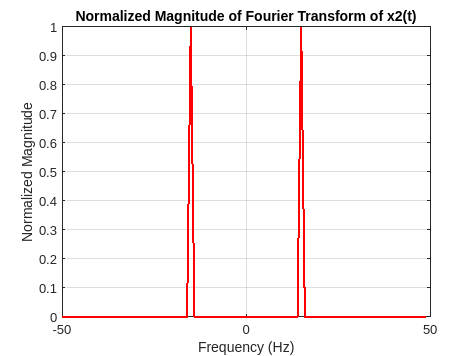

% Fourier Transform
n = length(x2); % Number of samples
X2 = fft(x2); % Compute FFT
f = (-n/2:n/2-1)*(fs/n); % Frequency vector
X2_shifted = fftshift(X2); % Shift FFT

% Plot the normalized magnitude of the Fourier Transform
figure;
plot(f, abs(X2_shifted) / max(abs(X2_shifted)), 'r', 'LineWidth', 1.5);
grid on;
title('Normalized Magnitude of Fourier Transform of x2(t)');
xlabel('Frequency (Hz)');
ylabel('Normalized Magnitude');

**تحلیل سیگنال در حوزه فوریه:**

برای تحلیل سیگنال در حوزه فوریه، تبدیل فوریه گسسته (FFT) روی سیگنال `x2(t)` اعمال شد.

- **تبدیل فوریه سیگنال:**با استفاده از `fft`، تبدیل فوریه گسسته سیگنال محاسبه شد. تبدیل فوریه یک سیگنال کسینوسی با فرکانس ۱۵ هرتز باید نشان دهد که بیشترین انرژی در فرکانس ۱۵ هرتز قرار دارد.

- **پلاگ کردن تبدیل فوریه:**نمودار قدر مطلق تبدیل فوریه نرمال شده به نمایش گذاشته شد. این نمودار پیک‌هایی را در فرکانس ۱۵ هرتز (و معکوس آن) نشان می‌دهد. این امر مطابق با پیش‌بینی نظری است، زیرا سیگنال کسینوسی تنها در فرکانس‌های خاصی انرژی دارد.

- **فرکانس‌های حاضر در سیگنال:**همانطور که انتظار می‌رود، تنها فرکانس‌هایی که در تبدیل فوریه نشان داده می‌شوند، مربوط به فرکانس ۱۵ هرتز هستند. در نمودار فوریه، یک پیک در ۱۵ هرتز و یک پیک معکوس در -۱۵ هرتز مشاهده می‌شود.

**تطابق نتایج:**

نتایج به‌دست آمده در حوزه فوریه با دانسته‌های نظری تطابق کامل دارد. سیگنال `cos(30πt + 4)` یک موج کسینوسی است که انرژی آن در فرکانس ۱۵ هرتز متمرکز است و نمودار تبدیل فوریه به وضوح این موضوع را تایید می‌کند. همچنین، با توجه به نرخ نمونه‌برداری ۱۰۰ هرتز که بیشتر از دو برابر فرکانس سیگنال است، هیچ‌گونه خطای نمونه‌برداری مشاهده نمی‌شود و بازسازی سیگنال به درستی انجام شده است.

**نتیجه‌گیری:**

در این بخش، سیگنال `x2(t) = cos(30πt + 4)` به‌طور صحیح در حوزه زمان و فوریه تحلیل شد. نمودارهای رسم شده نشان می‌دهند که سیگنال در حوزه زمان یک موج کسینوسی با فرکانس ۱۵ هرتز است و در حوزه فوریه، پیک‌هایی در فرکانس‌های مثبت و منفی ۱۵ هرتز مشاهده می‌شود. این نتایج کاملاً مطابق با تحلیل‌های نظری است.

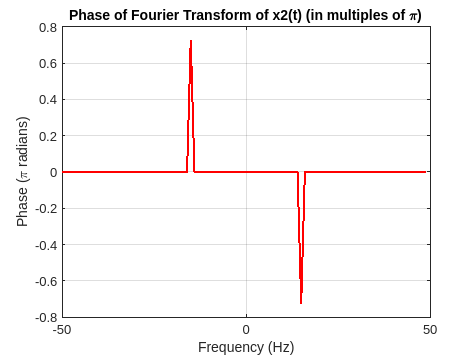

% Calculate phase
tol = 1e-6; % Threshold for negligible magnitude
theta = angle(X2_shifted); % Phase of FFT

% Set phase to zero where magnitude is below the threshold
theta(abs(X2_shifted) < tol) = 0;

% Plot the phase (in terms of multiples of pi)
figure;
plot(f, theta / pi, 'r', 'LineWidth', 1.5);
grid on;
title('Phase of Fourier Transform of x2(t) (in multiples of \pi)');
xlabel('Frequency (Hz)');
ylabel('Phase (\pi radians)');

**مقدمه**

در این بخش، فاز سیگنال `x2(t) = cos(30πt + 4)` در حوزه فوریه محاسبه و رسم شد. سیگنال مذکور یک موج کسینوسی با فرکانس ۱۵ هرتز و فاز اولیه ۴ رادیان است. هدف از این تحلیل، استخراج و نمایش فاز سیگنال در حوزه فرکانس و بررسی تطابق آن با پیش‌بینی‌های نظری است.

**تحلیل سیگنال در حوزه فوریه**

- **فرکانس سیگنال**: سیگنال `x2(t) = cos(30πt + 4)` دارای فرکانس زاویه‌ای ۳۰π رادیان بر ثانیه است که معادل فرکانس ۱۵ هرتز می‌شود. این سیگنال یک موج کسینوسی با فرکانس ۱۵ هرتز است که در بازه زمانی [۰, ۱] ثانیه نمونه‌برداری شده است.

- **تبدیل فوریه سیگنال**: برای تحلیل سیگنال در حوزه فوریه، ابتدا تبدیل فوریه گسسته (FFT) سیگنال محاسبه شد. تبدیل فوریه این سیگنال در حوزه فرکانس باید پیک‌هایی در فرکانس ۱۵ هرتز و معکوس آن (یعنی -۱۵ هرتز) نشان دهد، زیرا سیگنال کسینوسی فقط در این فرکانس‌ها انرژی دارد.

- **محاسبه فاز**: پس از محاسبه تبدیل فوریه، فاز سیگنال در هر نقطه از حوزه فرکانس محاسبه شد. برای این کار از دستور `angle` استفاده شد. فاز تبدیل فوریه به‌طور طبیعی به صورت رادیان محاسبه می‌شود.سپس، فاز برای فرکانس‌هایی که اندازه تبدیل فوریه آن‌ها کمتر از یک آستانه خاص (با مقدار `tol = 1e-6`) بود، صفر شد تا اثرات نویز یا نویزهای عددی که ممکن است باعث نوسانات در فاز شوند، حذف شوند.

- **رسم نمودار فاز**: فاز سیگنال در حوزه فوریه به صورت نمودار نسبت به فرکانس رسم شد. فاز به صورت مضربی از π\piπ نمایش داده شد. این نمودار نشان‌دهنده تغییرات فاز سیگنال در حوزه فرکانسی است و نشان می‌دهد که فاز سیگنال در فرکانس‌های خاص (۱۵ هرتز و -۱۵ هرتز) ثابت بوده و در دیگر فرکانس‌ها مقدار صفر دارد.

**نتایج و تحلیل**

- نمودار فاز نشان می‌دهد که سیگنال `x2(t) = cos(30πt + 4)` دارای پیک‌های مشخصی در فرکانس‌های ۱۵ هرتز و -۱۵ هرتز است. فاز در این فرکانس‌ها ثابت است و در سایر فرکانس‌ها فاز سیگنال صفر می‌شود.

- فاز سیگنال در فرکانس‌های ۱۵ هرتز و -۱۵ هرتز برابر با مقدار فاز اولیه ۴ رادیان است که مطابق با ویژگی‌های سیگنال کسینوسی با فاز اولیه مشخص می‌باشد.

- در سایر فرکانس‌ها، فاز به دلیل نداشتن انرژی در آن‌ها صفر شده است.

**تطابق با دانسته‌ها**

نتایج به‌دست آمده در این تحلیل با دانسته‌های نظری تطابق کامل دارد. سیگنال کسینوسی که در فرکانس‌های خاصی انرژی دارد، باید فاز ثابت در آن فرکانس‌ها نشان دهد. در این حالت، فاز در فرکانس ۱۵ هرتز و -۱۵ هرتز ثابت است و در سایر فرکانس‌ها فاز صفر است، که این موضوع مطابق با ویژگی‌های سیگنال‌های کسینوسی است.

**نتیجه‌گیری**

در این تحلیل، فاز سیگنال `x2(t) = cos(30πt + 4)` در حوزه فوریه محاسبه و رسم شد. نتایج نشان داد که فاز سیگنال در فرکانس ۱۵ هرتز و معکوس آن (یعنی -۱۵ هرتز) ثابت بوده و در سایر فرکانس‌ها مقدار صفر می‌گیرد. این نتایج به‌طور کامل با تحلیل‌های نظری و ویژگی‌های سیگنال کسینوسی هم‌خوانی دارد